# ECEN5463 | HW2

Collin Thornton

## Problem 1

Must find all values of $r \in \mathbb{R}$ such that the ball of radius $\bar B(0,r) \subset \mathbb{R}^m$ with resepct to $\dot x = f(x), x \in \mathbb{R}^m$ implies $\forall x \in \partial B(0,r), f^T(x)n(x)\leq0$

syms x1 x2 r th

X = [x1;x2];
f = [x1 + x2 - x1*(x1^2+x2^2);
     -2*x1 + x2 - x2*(x1^2 + x2^2)];

Equation of a circle: $x^2 +y^2 =r^2$

Normal vector = $<\cos \left(\theta \right),\sin \left(\theta \right)>$

Convert dynamics to polar coordinates

- 
$$r\dot{\;r} =x_1 \dot{x_1 } +x_2 \dot{\;x_2 }$$


- 
$$r^2 \dot{\;\theta \;} =x_1 \dot{\;x_2 } -x_2 \dot{\;x_1 }$$


n = [cos(th); sin(th)];

rrdot = simplify(x1*f(1)+x2*f(2));
r2the = simplify(x1*f(2)-x2*f(1));

rdot = simplify(subs(rrdot, [x1,x2], [r*cos(th), r*sin(th)])/r);
tdot = simplify(subs(r2the, [x1,x2], [r*cos(th), r*sin(th)])/r^2);

f_p = collect(simplify(subs(f, [x1,x2], [r*cos(th), r*sin(th)])))

$$f\_p = \left(\begin{array}{c} r\,\left(-\cos\left(\mathrm{th}\right)\,r^{2}+\cos\left(\mathrm{th}\right)+\sin\left(\mathrm{th}\right)\right)\\ -r\,\left(\sin\left(\mathrm{th}\right)\,r^{2}+2\,\cos\left(\mathrm{th}\right)-\sin\left(\mathrm{th}\right)\right) \end{array}\right)$$

%f_p = [rdot;tdot]

$$f\_p = \left(\begin{array}{c} -\frac{r\,\left(2\,r^{2}+\sin\left(2\,\mathrm{th}\right)-2\right)}{2}\\ {\sin\left(\mathrm{th}\right)}^{2}-2 \end{array}\right)$$

G = collect(simplify(transpose(f_p)*n))

$$G = \sin\left(\mathrm{th}\right)\,\left({\sin\left(\mathrm{th}\right)}^{2}-2\right)-\frac{r\,\cos\left(\mathrm{th}\right)\,\left(2\,r^{2}+2\,\cos\left(\mathrm{th}\right)\,\sin\left(\mathrm{th}\right)-2\right)}{2}$$

sol = solve(G,r)

$$sol = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{3}\,\cos\left(\mathrm{th}\right)+z\,{\cos\left(\mathrm{th}\right)}^{2}\,\sin\left(\mathrm{th}\right)-z\,\cos\left(\mathrm{th}\right)-{\sin\left(\mathrm{th}\right)}^{3}+2\,\sin\left(\mathrm{th}\right) \end{array}$$

Gdot = simplify(diff(G))

$$Gdot = \sin\left(\mathrm{th}\right)\,r^{3}-3\,r\,{\cos\left(\mathrm{th}\right)}^{3}+2\,r\,\cos\left(\mathrm{th}\right)-\sin\left(\mathrm{th}\right)\,r-3\,{\cos\left(\mathrm{th}\right)}^{3}+\cos\left(\mathrm{th}\right)$$

subs(Gdot, r, sol(1))

$$ans = \begin{array}{l} -3\,{\cos\left(\mathrm{th}\right)}^{3}\,\sigma_{1}-3\,{\cos\left(\mathrm{th}\right)}^{3}+2\,\cos\left(\mathrm{th}\right)\,\sigma_{1}+\cos\left(\mathrm{th}\right)+\sin\left(\mathrm{th}\right)\,{\sigma_{1}}^{3}-\sin\left(\mathrm{th}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}\,\cos\left(\mathrm{th}\right)+z\,{\cos\left(\mathrm{th}\right)}^{2}\,\sin\left(\mathrm{th}\right)-z\,\cos\left(\mathrm{th}\right)-{\sin\left(\mathrm{th}\right)}^{3}+2\,\sin\left(\mathrm{th}\right),z,1\right) \end{array}$$

p2 = subs(Gdot,r,sol(2))

$$p2 = \begin{array}{l} -3\,{\cos\left(\mathrm{th}\right)}^{3}\,\sigma_{1}-3\,{\cos\left(\mathrm{th}\right)}^{3}+2\,\cos\left(\mathrm{th}\right)\,\sigma_{1}+\cos\left(\mathrm{th}\right)+\sin\left(\mathrm{th}\right)\,{\sigma_{1}}^{3}-\sin\left(\mathrm{th}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}\,\cos\left(\mathrm{th}\right)+z\,{\cos\left(\mathrm{th}\right)}^{2}\,\sin\left(\mathrm{th}\right)-z\,\cos\left(\mathrm{th}\right)-{\sin\left(\mathrm{th}\right)}^{3}+2\,\sin\left(\mathrm{th}\right),z,2\right) \end{array}$$

figure()
fplot(p2, "DisplayName", "h(th)")

p3 = simplify(subs(Gdot,r,sol(3)))

$$p3 = \begin{array}{l} -3\,{\cos\left(\mathrm{th}\right)}^{3}\,\sigma_{1}-3\,{\cos\left(\mathrm{th}\right)}^{3}+2\,\cos\left(\mathrm{th}\right)\,\sigma_{1}+\cos\left(\mathrm{th}\right)+\sin\left(\mathrm{th}\right)\,{\sigma_{1}}^{3}-\sin\left(\mathrm{th}\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}\,\cos\left(\mathrm{th}\right)+z\,{\cos\left(\mathrm{th}\right)}^{2}\,\sin\left(\mathrm{th}\right)-z\,\cos\left(\mathrm{th}\right)-{\sin\left(\mathrm{th}\right)}^{3}+2\,\sin\left(\mathrm{th}\right),z,3\right) \end{array}$$

hold on
fplot(p3, "DisplayName", "-h(th)")
legend()

## Problem 2 

### 2-1 Show that the system $\dot{x} =x^2$ admits solutions that blow up to infinity in finite time

## Problem 3 Prove wheter the following functions are continous from $\mathbb{R}$ to $\mathbb{R}$

Continuous functions $f\left(x\right)$ must satisfy the following points to be called piecewise continous:

- $t\to f\left(t,x\right)$contains a finite number of discontinuties at $t\in J$

- 
$$\forall \;t\in J,\lim_{h\to 0^+ } f\left(t+h,x\right)\;\mathrm{and}\;\lim_{h\to 0^- } \;f\left(t+h,x\right)\;\mathrm{exist}\;\mathrm{and}\;\mathrm{are}\;\mathrm{finite}$$


### 3-1 $f\left(x\right)=\max \left(0,x\right)$

syms x

f = x*heaviside(x);
disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)   

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\max \left(0,x\right)$ is **continous**.

### 3-2 $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$

syms x
f = sin(x)*heaviside(x);

disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$ is **continous**.

### 3-3 $f\left(x\right)=\mathrm{sgn}\left(x\right)=\left\lbrace \begin{array}{ll}
1 & x>0\\
-1 & x<0\\
0 & x=0
\end{array}\right.$

syms x

f = piecewise(x<0, -1, x==0, 0, x>0, 1);

disc =  feval(symengine, 'discont', f, x) 

$$disc = \left\{0\right\}$$

There is only one discontinous point

limit(f,x,0,'left')

$$ans = -1$$

limit(f,x,0,'right')

$$ans = 1$$

subs(f,x,0)                        

$$ans = 0$$

Both limits exist, though they are not equivalent. Therefore $f\left(x\right)=\mathrm{sgn}\left(x\right)$ is **not continuous**. (Though it is piecewise continuous)

## Problem 4

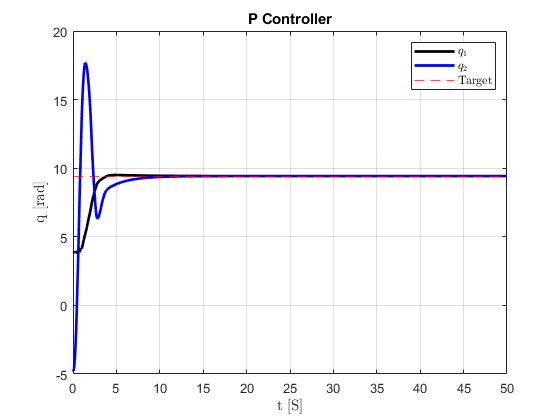

% Set the initial condition for the state and the time interval for integration

% x = [q1;q2;dq1;dq2];
x0 = 10*(rand(4,1)-0.5);
tspan = linspace(0,50,1000);

P = cell(2,1);
P{1} = [3.473;0.196;0.242];

% Solve the ode using 'ode45'.
P{2} = "P";
[t,x] = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);
% Read the documentation of 'ode45' to find out the format of the output,
% x, so that you can generate the required plots.

figure()

plot(t,x(:,1), '-k', "LineWidth", 2)
hold on;
plot(t,x(:,2), '-b', "LineWidth", 2)
yline(3*pi, '--r')

title("P Controller")
grid on
legend("$q_1$", "$q_2$", "Target", "Interpreter", "latex")
xlabel("t [S]", "Interpreter", "latex")
ylabel("q [rad]", "Interpreter", "latex")

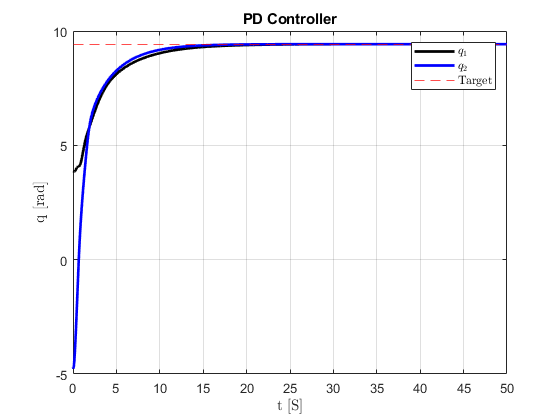

% Solve the ode using 'ode45'.
P{2} = "PD";
[t,x] = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);
% Read the documentation of 'ode45' to find out the format of the output,
% x, so that you can generate the required plots.

figure()

plot(t,x(:,1), '-k', "LineWidth", 2)
hold on;
plot(t,x(:,2), '-b', "LineWidth", 2)
yline(3*pi, '--r')

title("PD Controller")
grid on
legend("$q_1$", "$q_2$", "Target", "Interpreter", "latex")
xlabel("t [S]", "Interpreter", "latex")
ylabel("q [rad]", "Interpreter", "latex")

% Solve the ode using 'ode45'.
P{2} = "PID";
[t,x] = ode45(@(t,x) closedLoopDynamics(t,x,P), tspan, x0);

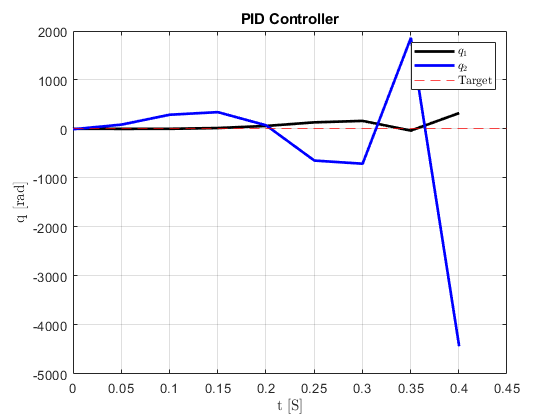

% Read the documentation of 'ode45' to find out the format of the output,
% x, so that you can generate the required plots.

figure()

plot(t,x(:,1), '-k', "LineWidth", 2)
hold on;
plot(t,x(:,2), '-b', "LineWidth", 2)
yline(3*pi, '--r')

title("PID Controller")
grid on
legend("$q_1$", "$q_2$", "Target", "Interpreter", "latex")
xlabel("t [S]", "Interpreter", "latex")
ylabel("q [rad]", "Interpreter", "latex")

function x_dot = closedLoopDynamics(t, x, P)
    % This function "simulates" the behavior of a two-link robot under the
    % controller given by the 'control' function.
    x_dot = openLoopDynamics(t, x, control(t,x,P{2}), P);
end


function x_dot = openLoopDynamics(t, x, u, P)
    % This function "simulates" the behavior of a two-link robot
    % manipulator using a model in the state space form. 
    %
    % TODO: Use the given equations to compute x_dot using t, x, and u
    p = P{1};
    
    M = [p(1)+2*p(3)*cos(x(2)), p(2)+p(3)*cos(x(2));
         p(2) + p(3)*cos(x(2)), p(2)];
    V = [-p(3)*sin(x(2))*x(4), -p(3)*sin(x(2))*(x(3)+x(4));
         p(3)*sin(x(2))*x(3), 0];
    F = [8.45*tanh(x(3)); 2.35*tanh(x(4))];
    
    ddq = M\(u - V*x(3:4) - F);
    x_dot = [x(3:4);ddq];
end

function u = control(t, x, c)
    % This function calculates the control signal (a vector containing the
    % torque commands for the two joints of the two-link robot) as a
    % function of time and state
    % Use the given equations to compute u using from t and x here
    persistent E t0 e0
    
    if isempty(E)
        E = zeros(2,1);
    end
    if isempty(t0)
        t0 = 0;
    end
    if isempty(e0)
        e0 = 0;
    end
    
    e = [3*pi;3*pi] - x(1:2);
    dt = t-t0;
    de = e-e0;
        
    t0 = t;
    e0 = e;
    
    kP = [2;1];
    kI = [0.1;0.1];
    kD = [1;1];
    
    P = [0;0]; I = [0;0]; D = [0;0];

        
    if contains(c,'P')    
        P = kP.*e;
    end
    
    if contains(c, 'I')
        I = kI.*(E+e*(dt));
    end
    
    if contains(c,'D')
        if dt == 0
            D = [0;0];
        else
            D = kD.*(de/dt);
        end
    end

    E = E + e;
    u = P + I + D;    
end